Question 2.1

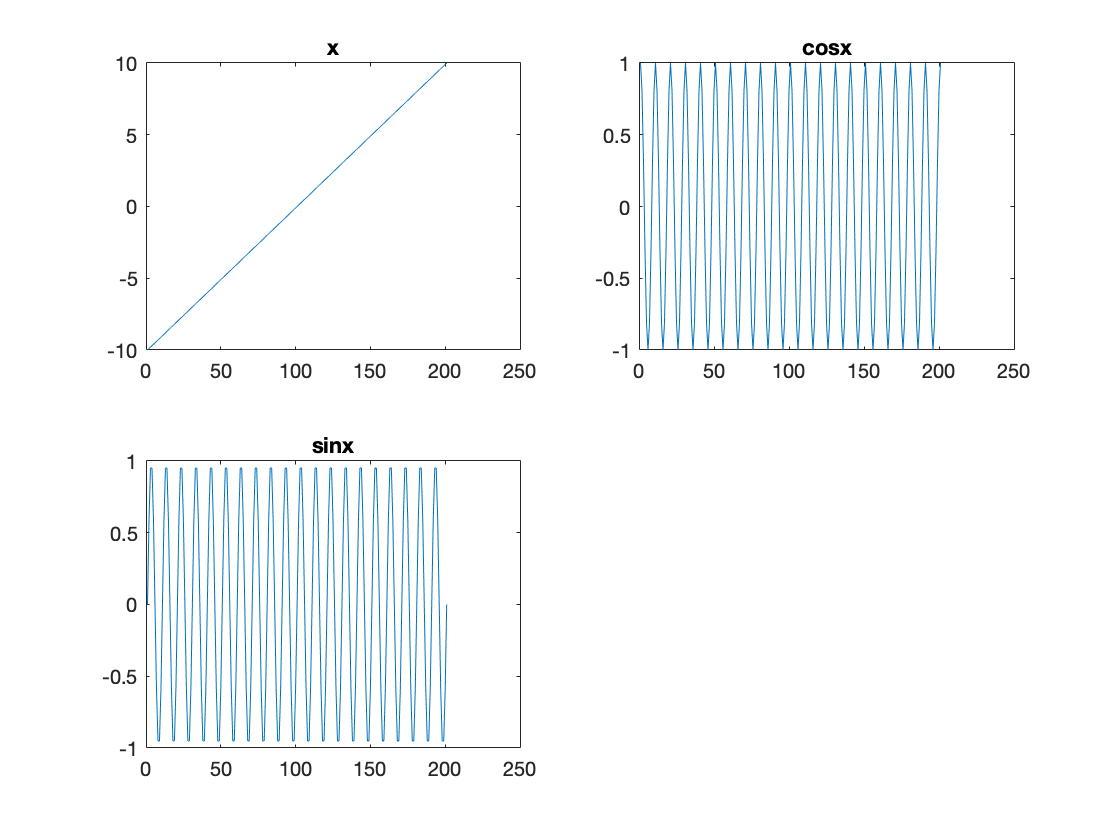

x=-10:0.1:10;
%x=-10:1.1:10;
%sampling period=1.1 or 0.1
%sampling frequency= 1/1.1=0.91 Hz
%sampling frequency= 1/0.1=10 Hz
%we are not fulfilling the sampling theorem when increasing

cosx = cos(2 * pi * x);
sinx = sin(2 * pi * x);

figure
subplot(221)
plot(x)
title('x');

subplot(222)
plot(cosx)
title('cosx');

subplot(223)
plot(sinx)
title('sinx');

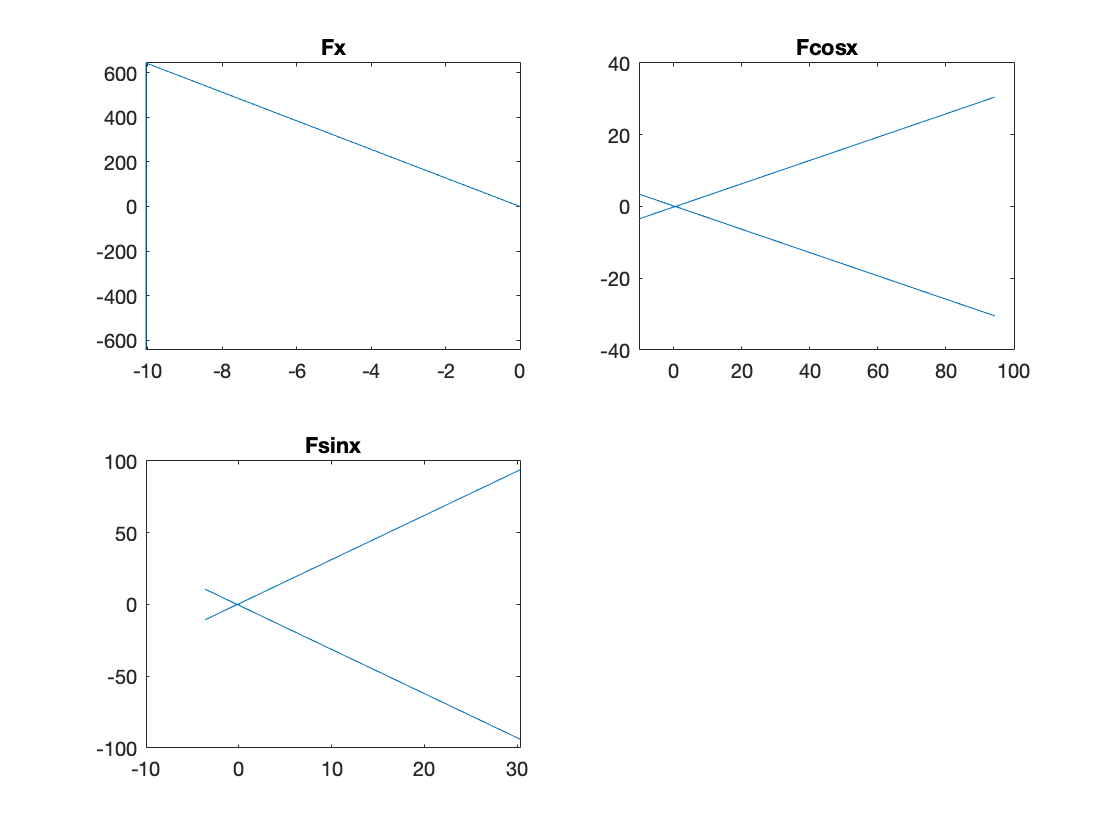


Fx = fft(x);
Fcosx = fft(cosx);
Fsinx = fft(sinx);

figure 

subplot(221)
plot(Fx)
title('Fx');

subplot(222)
plot(Fcosx)
title('Fcosx');

subplot(223)
plot(Fsinx)
title('Fsinx');



%fourier transform gives us a complex number
%fft->amp*expp(itheta)
%Y=fft(y)
%time vector: x=0:0.1:10;
%sin(2 pi x)=sin( 2 pi t) - assuming that frequency is 1
%2 pi f t

Question 2.2

Y=fft(y)

absY=abs(Y)

phaseY=angle(Y)

subplot(2,1,1)

plot(absY)

Title('Amplitude spectrum')

subplot(2,1,2)

plot(phaseY)

Ttitle('phase spectrum')

Y=Fcosx

Y =    1.0000 + 0.0000i   1.0023 + 0.0157i   1.0093 + 0.0316i   1.0213 + 0.0479i   1.0386 + 0.0650i   1.0617 + 0.0831i   1.0915 + 0.1027i   1.1290 + 0.1240i   1.1760 + 0.1478i   1.2345 + 0.1748i   1.3076 + 0.2060i   1.3998 + 0.2431i   1.5179 + 0.2881i   1.6725 + 0.3446i   1.8812 + 0.4183i   2.1755 + 0.5196i   2.6176 + 0.6686i   3.3503 + 0.9117i   4.7877 + 1.3837i   8.8514 + 2.7087i  94.3150 +30.4819i -10.1537 - 3.4578i  -4.6612 - 1.6691i  -2.9601 - 1.1125i  -2.1339 - 0.8402i  -1.6467 - 0.6783i  -1.3261 - 0.5707i  -1.0996 - 0.4937i  -0.9314 - 0.4358i  -0.8017 - 0.3905i  -0.6989 - 0.3541i  -0.6156 - 0.3240i  -0.5467 - 0.2988i  -0.4890 - 0.2773i  -0.4400 - 0.2586i  -0.3978 - 0.2423i  -0.3613 - 0.2279i  -0.3294 - 0.2150i  -0.3013 - 0.2034i  -0.2764 - 0.1930i  -0.2542 - 0.1834i  -0.2343 - 0.1747i  -0.2163 - 0.1667i  -0.2001 - 0.1592i  -0.1854 - 0.1523i  -0.1721 - 0.1459i  -0.1598 - 0.1399i  -0.1486 - 0.1343i  -0.1383 - 0.1289i  -0.1289 - 0.1239i


absY=abs(Y);
phaseY=angle(Y);

fs=1/1.1

fs = 0.9091

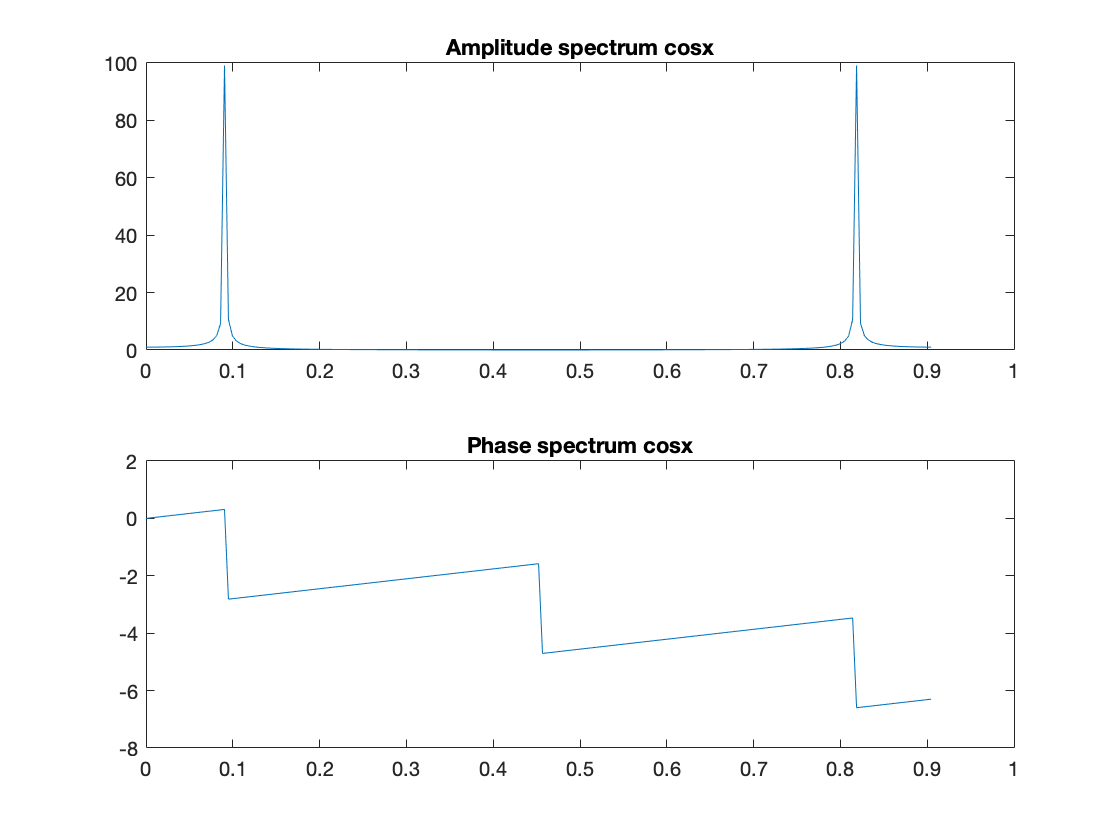

f=((0:length(Y)-1)*fs)/length(Y);

figure
subplot(211);
plot(f,absY);
title('Amplitude spectrum cosx');
%what are the frequencies that contribute to 
%the signal and what is the contribution,
% thats is why i dont see any difference
%x-axis neet to create vector of frequencies consisten with a signal 
%f=((0:length(Y)-1)*Fs(sampling frequency)/length(Y)
%sampling frequency: 10Hz

subplot(212);
plot(f,unwrap(phaseY));
title('Phase spectrum cosx');

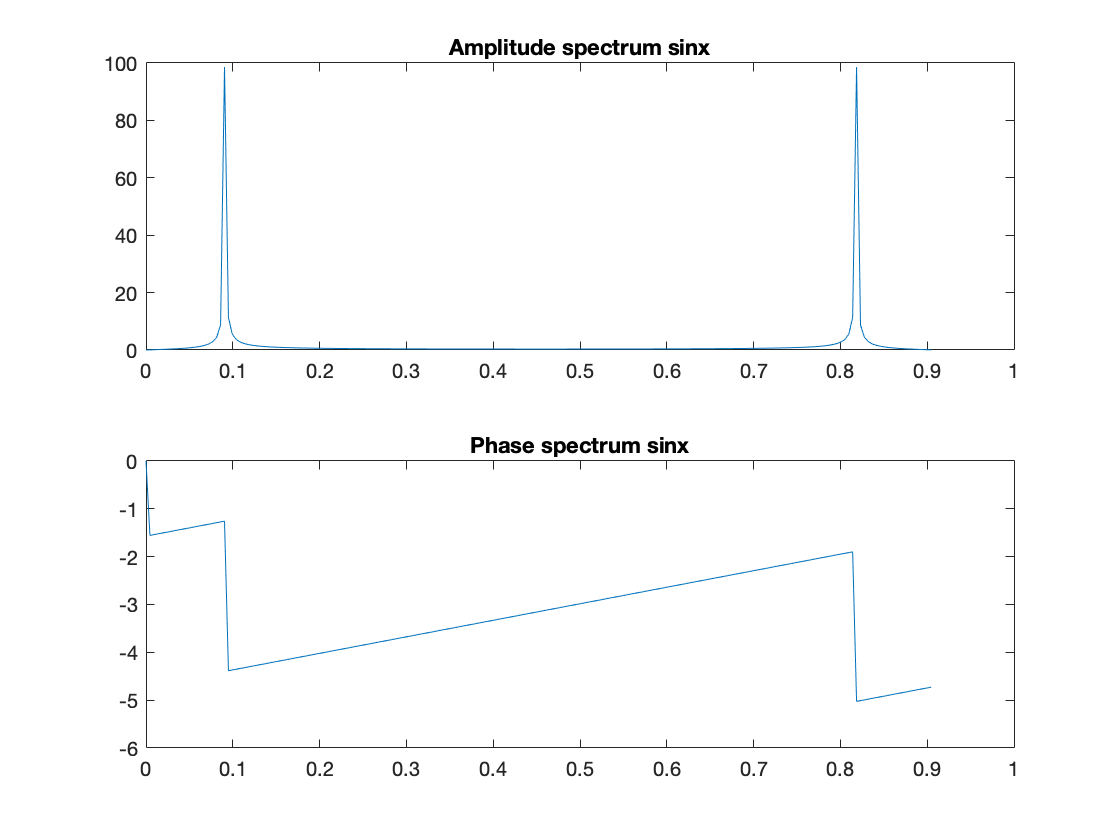

%contains information about a shape: phase shift, i can see the difference now
figure

Y2=Fsinx;
absY2=abs(Y2);
phaseY2=angle(Y2);

subplot(211);
plot(f,absY2);
title('Amplitude spectrum sinx');

subplot(212);
plot(f,unwrap(phaseY2));
title('Phase spectrum sinx');

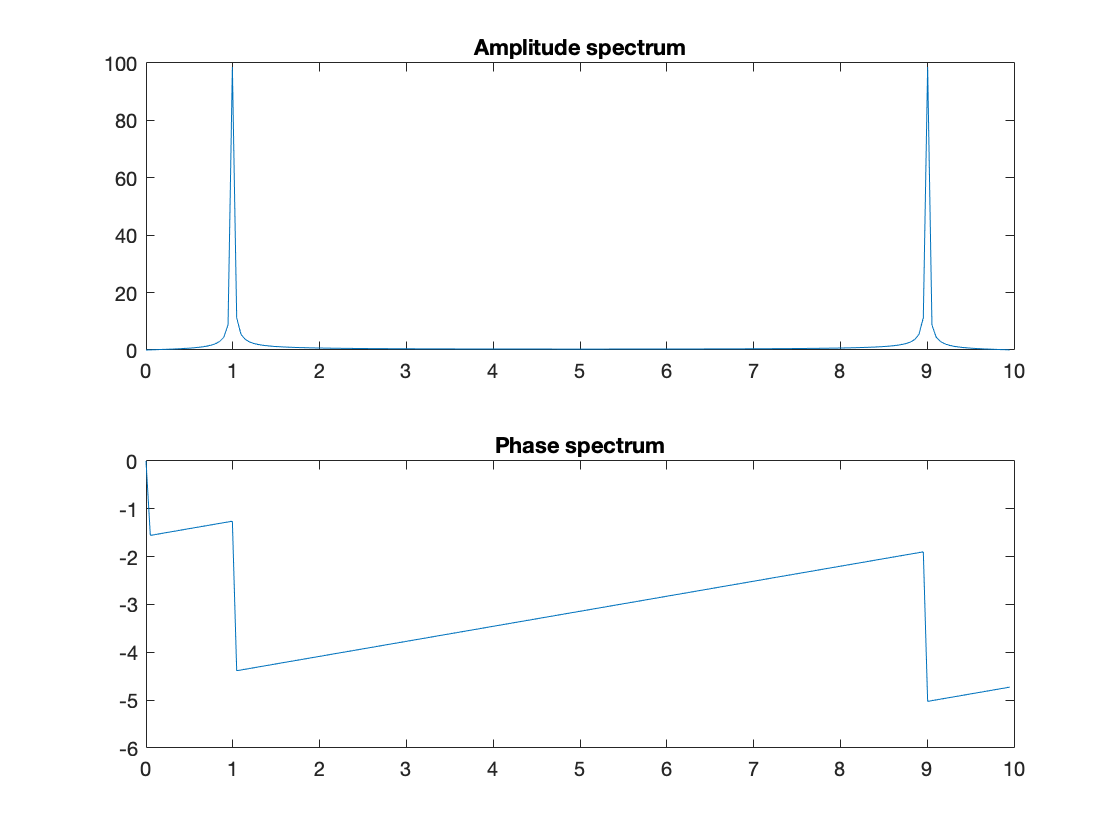

clear

x=-10:0.1:10;

sinx = sin(2 * pi * x);

plotfft(sinx, 1/0.1);

Question 2.3

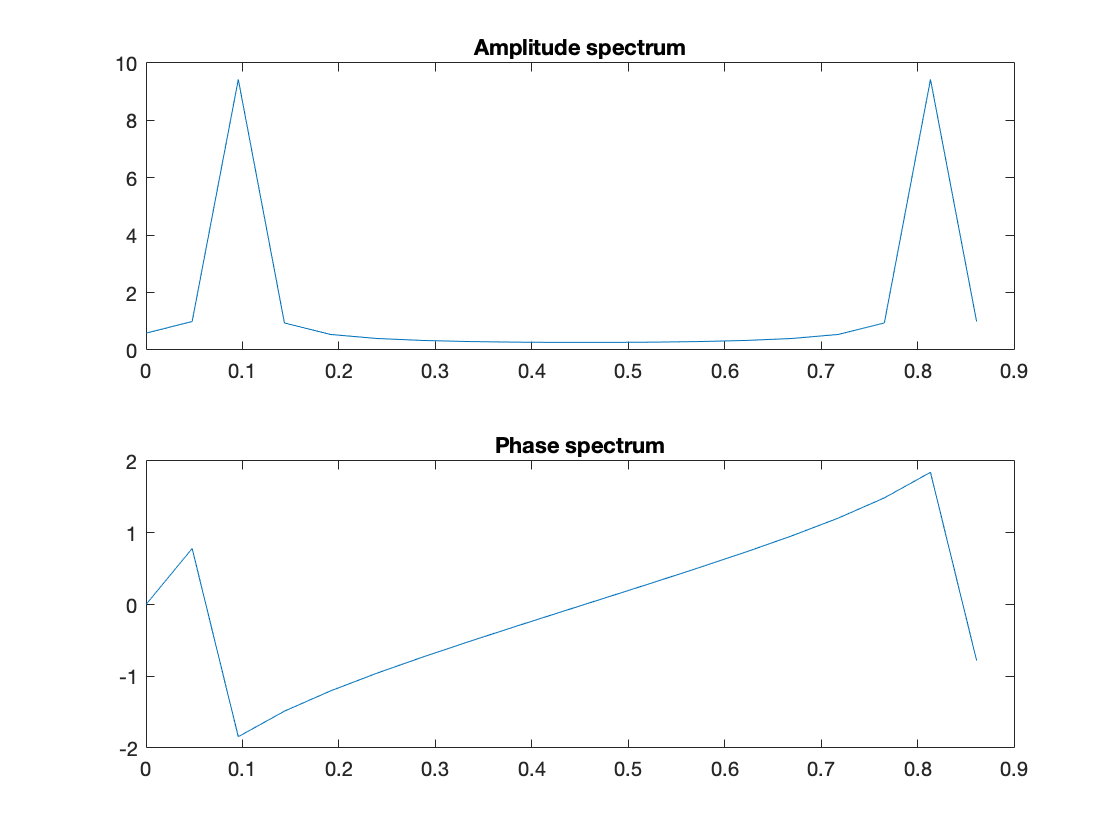

clear

x=-10:1.1:10;

sinx = sin(2 * pi * x);

plotfft(sinx, 1/1.1);

Question 2.4

Power line intereference = 50 Hz

Removing interference, we have to apply square window to remove 50Hz frequency.

x=[0,1,-1,5,2,1]

x(4)=0

x=[0,1,-1,0,2,1]

Take interval of that position and make it equal to 0

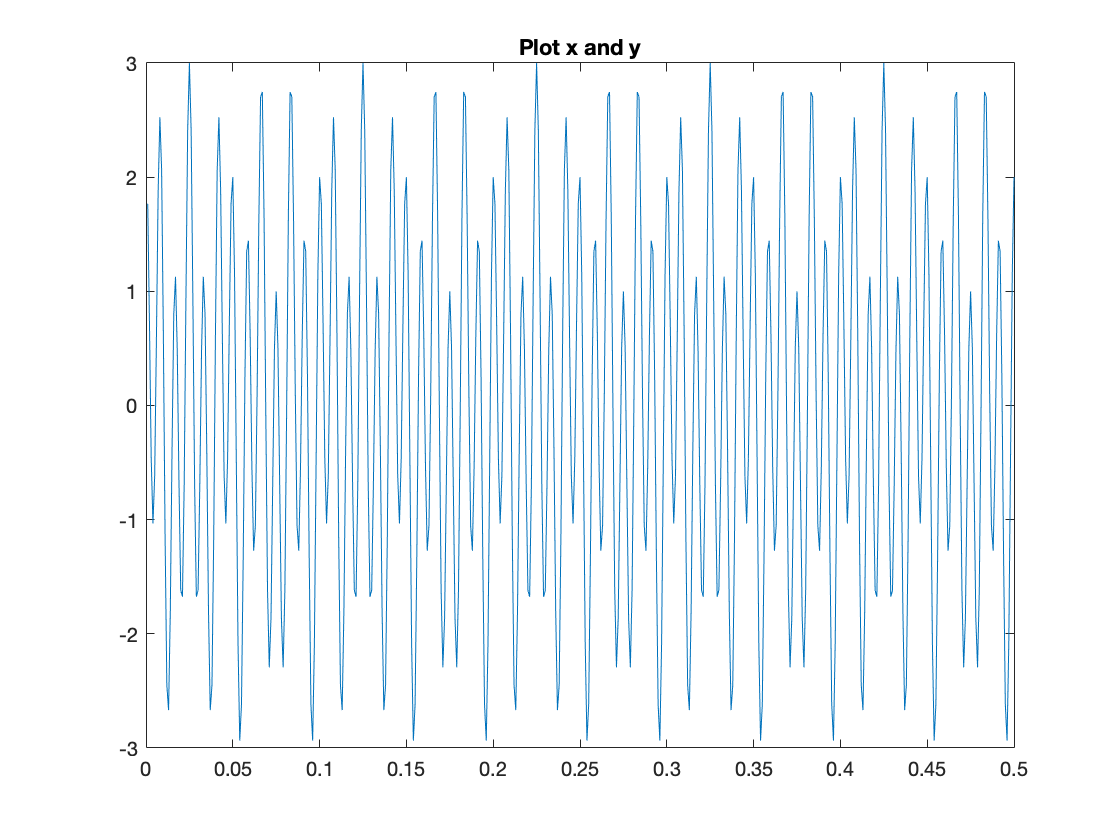

clear
load('dataset1.mat')
%data = importdata('dataset1.mat')

plot(x,y)
title('Plot x and y');

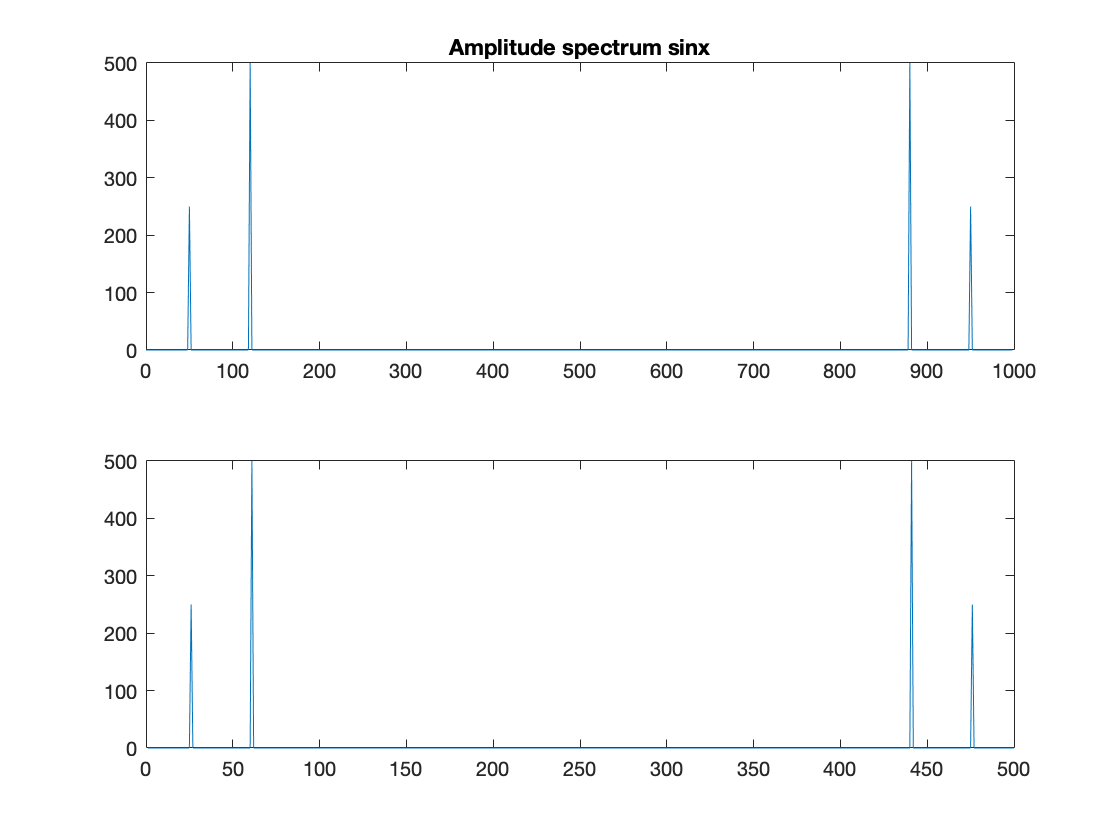

Y = fft(y);
fs=1000;

%plotfft(y, fs);

f=((0:length(Y)-1)*fs)/length(Y);

figure
subplot(211);
plot(f,abs(Y));
title('Amplitude spectrum sinx');

subplot(212);
plot(f,unwrap(angle(Y)));
title('Phase spectrum sinx');

%we need to find the index - position (plotting with f gives us frequency)

plot(abs(Y))

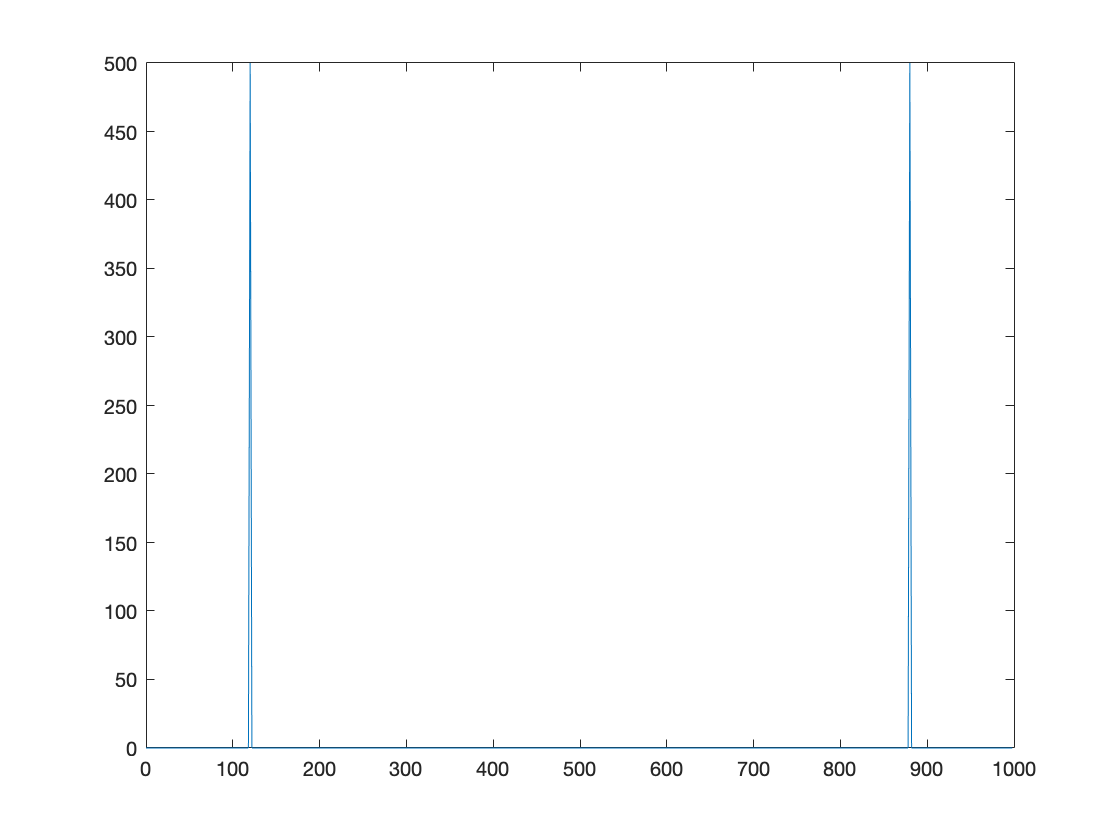

%between 0 and 30 I will be ok, 
%but we also need to get rid of the interference on the other side

filteredY = Y; 
%filteredY([1:30, end-30:end]) = 0;
peaklocation=find(abs(f - 55)<2,1,'first');
filteredY([1:peaklocation, end-peaklocation:end]) = 0;

figure
plot(f,abs(filteredY))

Question 2.5

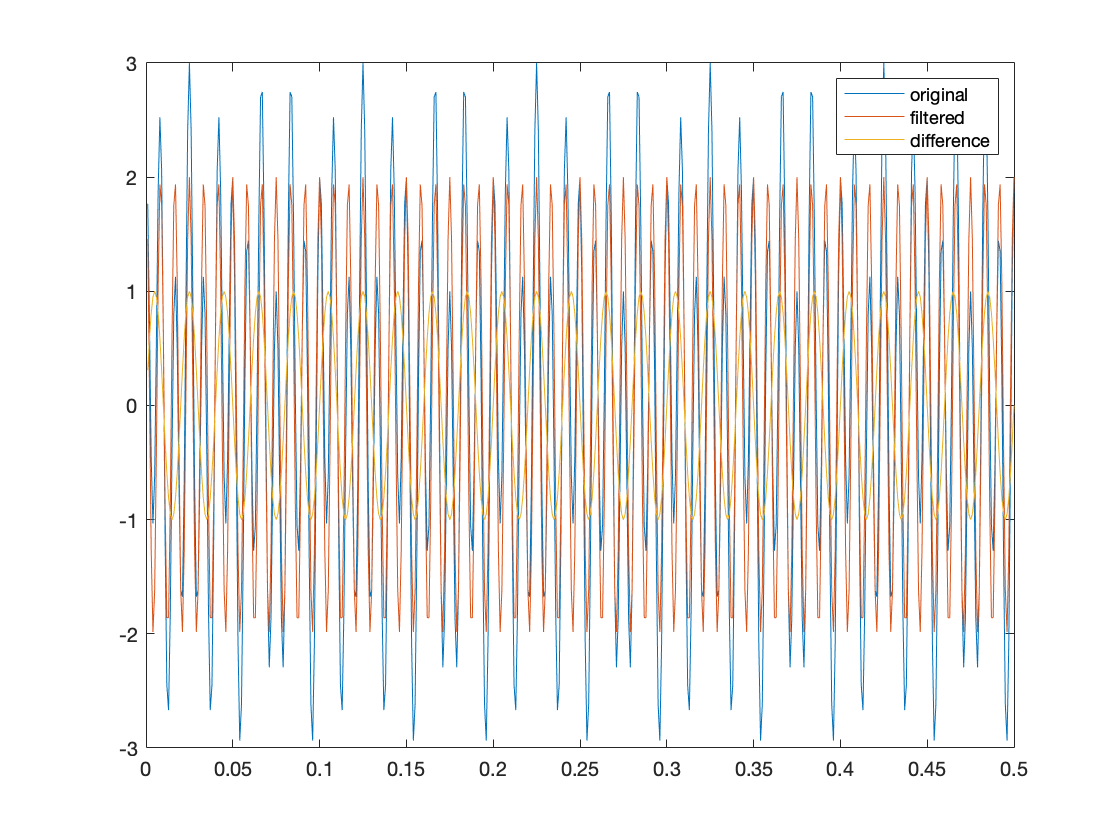

%yfiltered = ifft(filteredY)
yfiltered = real(ifft(filteredY));
figure
plot(x,y,x,yfiltered,x,y-yfiltered)
legend('original', 'filtered', 'difference')


%yellow is a power line


Question 2.6

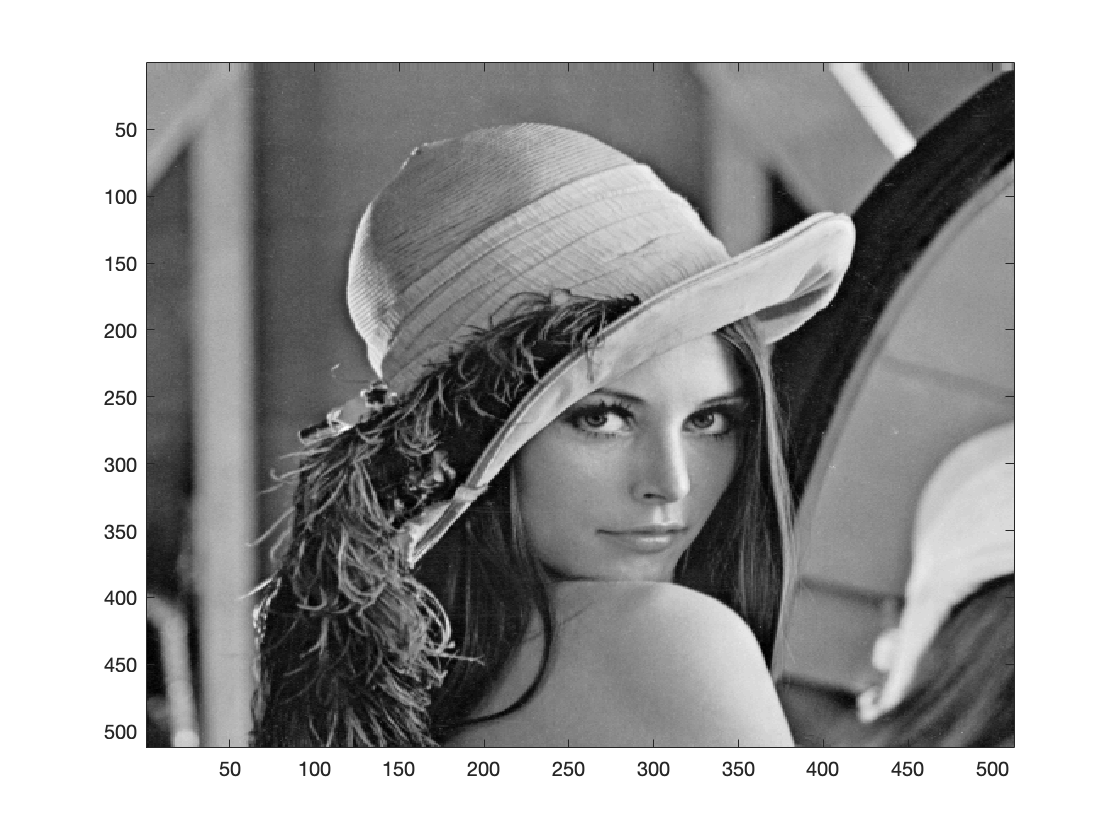

clear

im=imread('lena_gray.tif');
im=double(im);

imagesc(im)
colormap gray

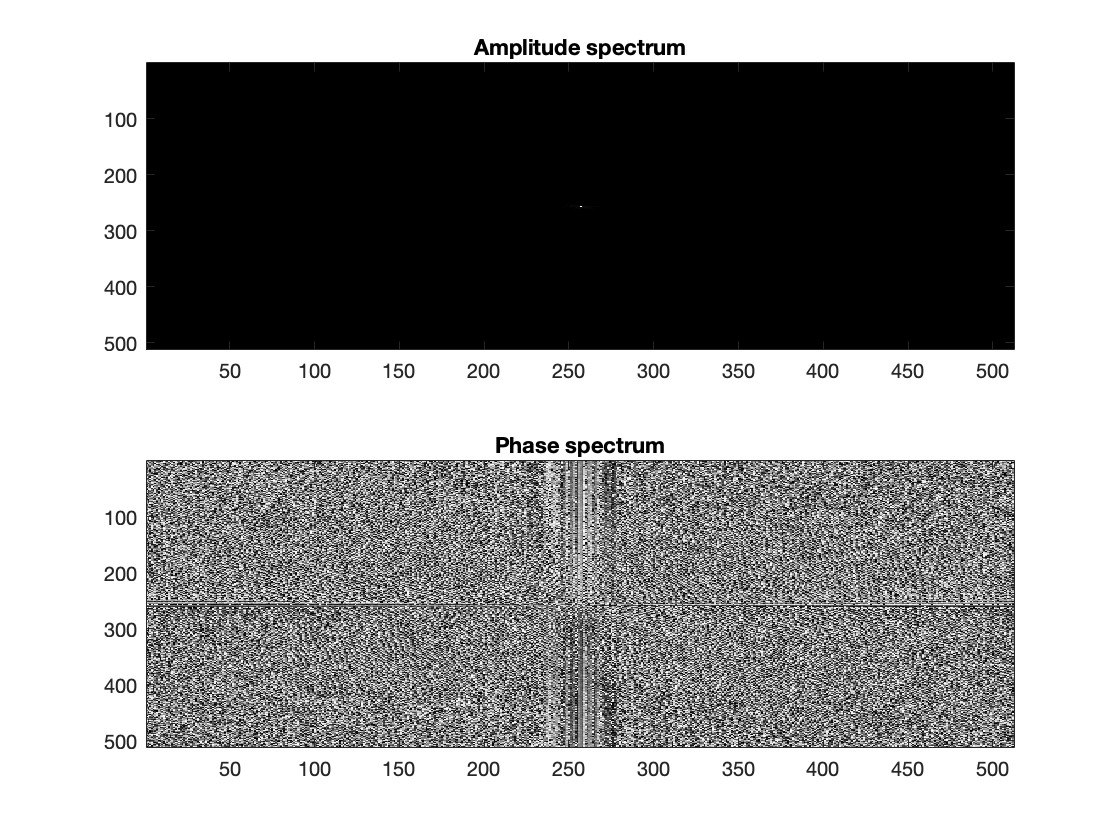


%f = 1:length(im);
im_fft = fft2(im);
spectrum = fftshift(abs(im_fft));
phase=fftshift(angle(im_fft));

figure;

subplot(211);
imagesc(spectrum)
colormap gray
title('Amplitude spectrum');

subplot(212);
imagesc((phase))
colormap gray
title('Phase spectrum');

Question 2.7

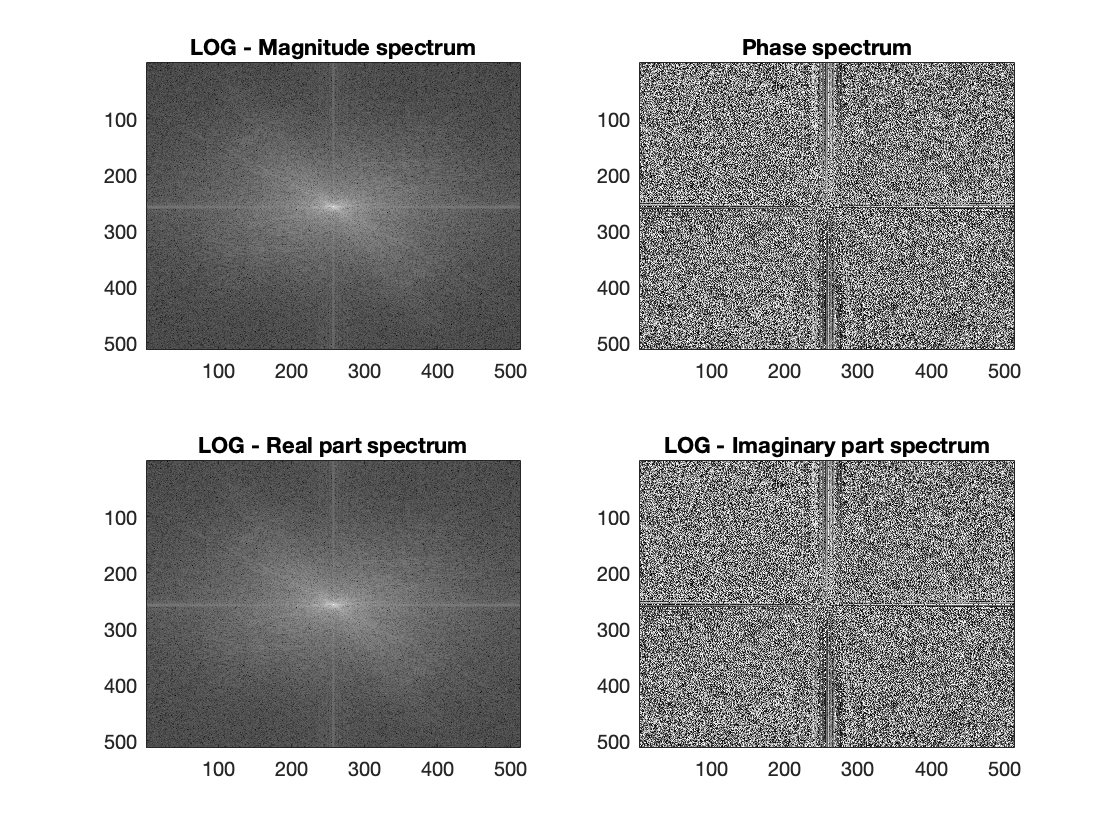

figure;
subplot(221);
imagesc(fftshift(log(abs(im_fft)+1)));
colormap gray
title('LOG - Magnitude spectrum');

subplot(222);
imagesc(fftshift((angle(im_fft))));
colormap gray
title('Phase spectrum');

subplot(223);
imagesc(fftshift(real(log(im_fft+1))));
colormap gray
title('LOG - Real part spectrum');

subplot(224);
imagesc(fftshift(imag(log(im_fft+1))));
colormap gray
title('LOG - Imaginary part spectrum');

Quetion 2.8

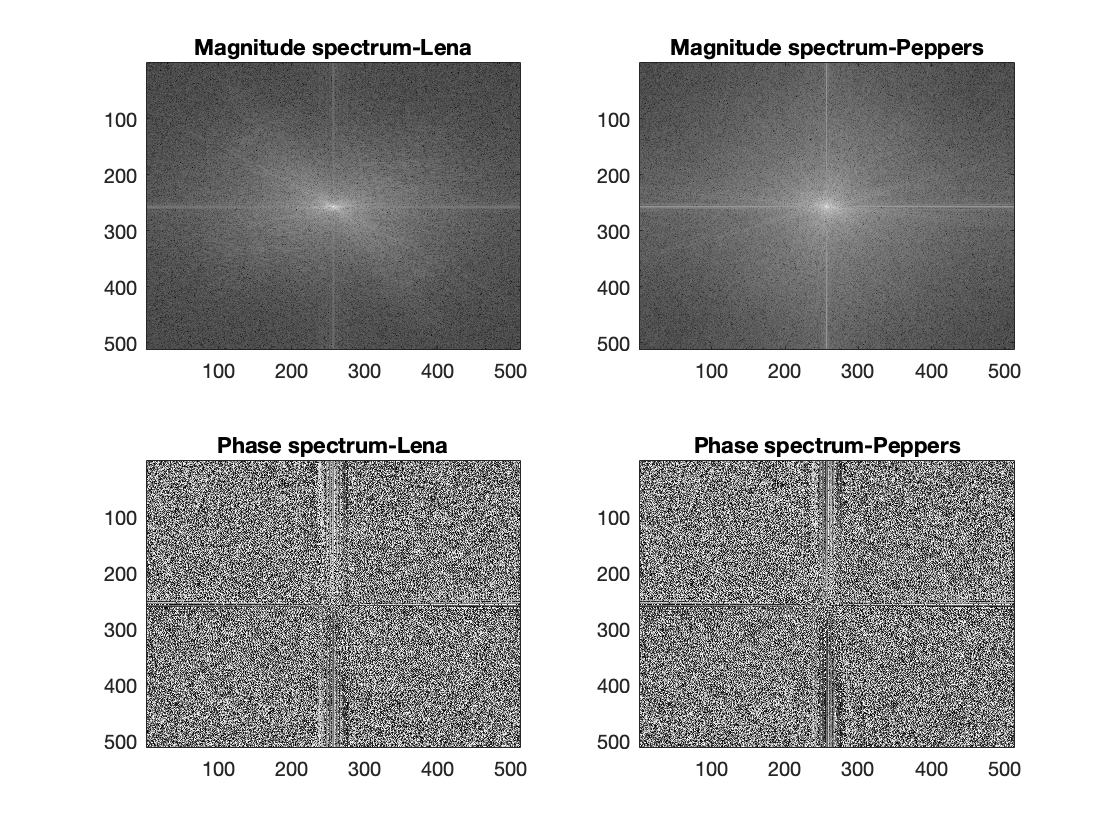

clear

im1 = double(imread('lena_gray.tif'));
im2 = double(imread('peppers_gray.tif'));

%Fourier Transform on both images
im1_fft = fft2(im1);
im2_fft = fft2(im2);

%Split the information into its magnitude and phase part
%lena
im1M = abs(im1_fft);
im1P = angle(im1_fft);
%peppers
im2M = abs(im2_fft);
im2P = angle(im2_fft);

%Combination of images:
%im1 magnitude with im2 phase
im12_ftt = im1M.*(cos(im2P)+1i*sin(im2P));
%im2 magnitude with im1 phase
im21_fft = im2M.*(cos(im1P)+1i*sin(im1P));

%Inverse Fourier Transform
im1_ifft=ifft2(im12_ftt);
im2_ifft=ifft2(im21_fft);

figure;
subplot(2,2,1);
imagesc(fftshift(log(im1M)));
colormap gray
title('Magnitude spectrum-Lena');
subplot(2,2,2);
imagesc(fftshift(log(im2M)));
colormap gray
title('Magnitude spectrum-Peppers');

subplot(2,2,3);
imagesc(fftshift(im1P));
colormap gray
title('Phase spectrum-Lena');

subplot(2,2,4);
imagesc(fftshift(im1P));
colormap gray
title('Phase spectrum-Peppers');

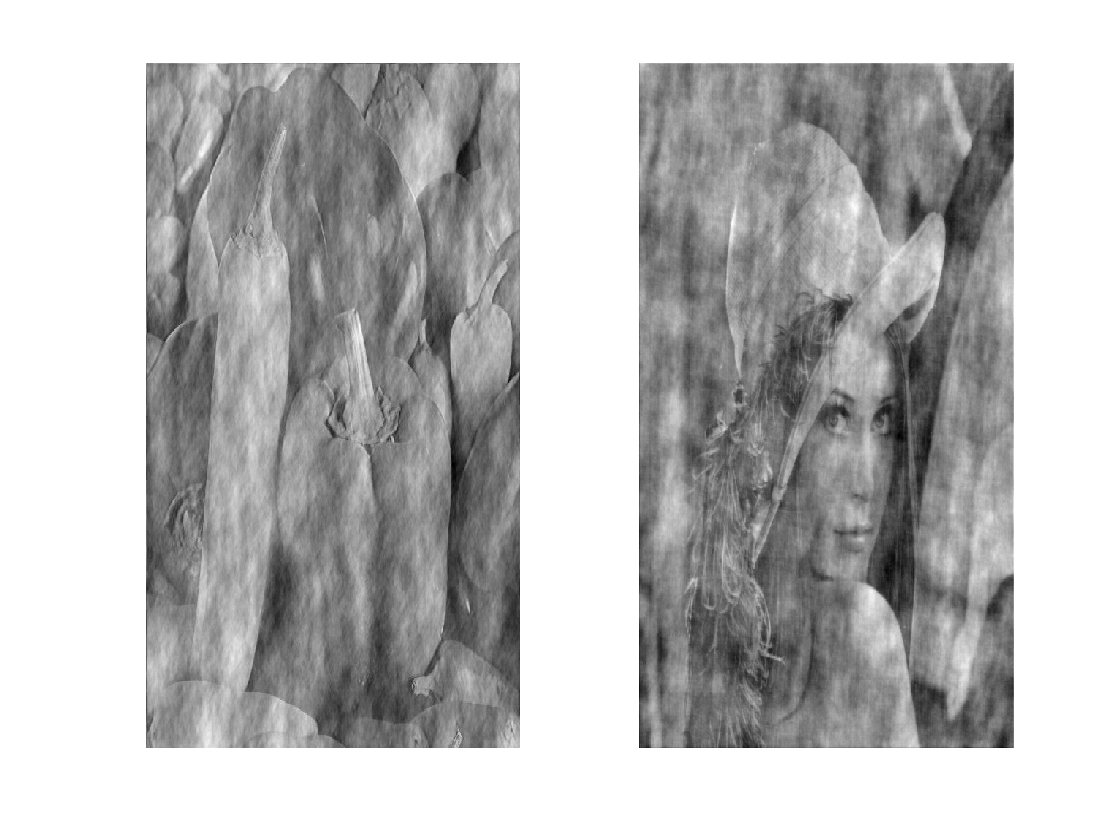


% subplot(3,2,5);
% imagesc(fftshift(real(log(im12_ftt))));
% colormap gray
% title('Combination im1M with im2P');
% subplot(3,2,6);
% imagesc(fftshift(imag(log(im21_fft))));
% colormap gray
% title('Combination im2M with im1P');


figure;
subplot(1,2,1);
imagesc(real(im1_ifft)), axis off
colormap gray

subplot(1,2,2);
imagesc(real(im2_ifft)), axis off
colormap gray